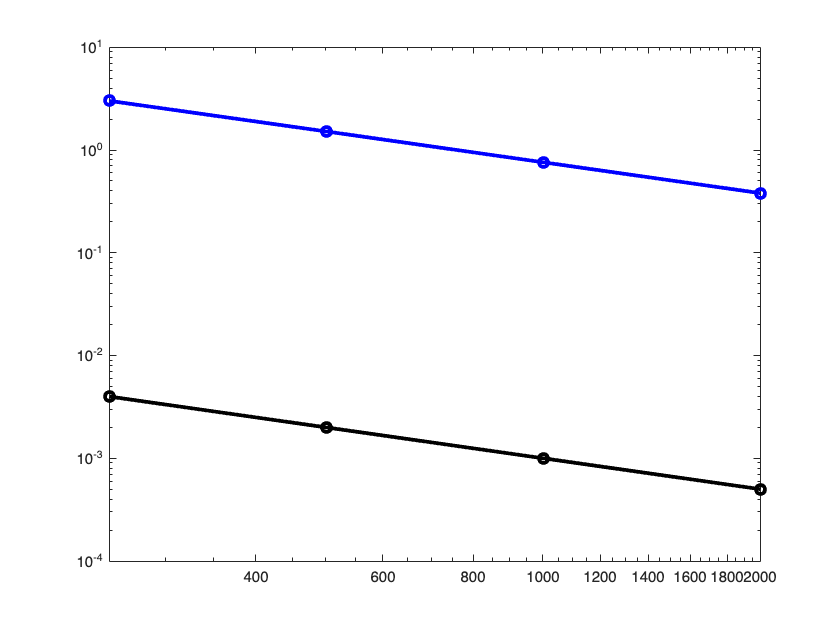

%Starting/ending (day)
t0 = 0; 
tF = 50;

%timestep
h = 1/24;
time = t0:h:tF;

%Initial value of biomass at time t0 (tons)
x0 = 20;

%The maximum sustainable fish biomass.
%xx = 99999;

%the natural growth function
syms x real
g =@(x) 0.05*x;
sym_derr = diff(g(x));
derr_g = matlabFunction(sym_derr);

%the rate of fishing effort at time t(tons/time)
u0 =@(t) sin(t); %ones(1,1 + (tF-t0)/h).*5;
%u0 = zeros(1,length(time(1:end-1)));
du0 = cos(time(1:end-1));

%the catchability coefficient(1/tons)
q = 0.0001;

%the discount rate(no unit)
rho = 0.1;

%the unit price of landed fish(money/tons)
p = 3000;

%the unit cost of (money/tons)
c = 1;

%derivative of x w.r.t. t
f =@(t,x,u) g(x) - q.*u.*x;

%[th, uh] = explicit_euler(u0, f, t0, tF, x0,  h);
y = @(t) exp(0.05*t+q*cos(t)+log(x0)-q);



timestep = [1/5, 1/10, 1/20, 1/40];
ns = zeros(1,4);
errorexp = zeros(1,4);

for i=1:4
    [th, uh] = explicit_euler(u0, f, t0, tF, x0,  timestep(1,i));
    y_sol = y(th);
    errorexp(1,i) = max(abs(y_sol-uh));
    ns(1,i) = length(th);
end

loglog(ns,errorexp,"o-b",'LineWidth', 2.5)
hold on;
bound = ns.^(-1);
loglog(ns,bound,"o-k",'LineWidth', 2.5)
hold  off;